# Plot example traces

clear % clear all variables in the workspace
close all % close any figure windows that might be open
clc

addpath(genpath('./lib'))

## Part 0: Initialization

Specify the dataset to analyze

% We need to specify the prefix of the project we wish to analyze
Prefix = '2020-11-24-optoknirps_eve4_6_embryo7'; APflip = 0;


Initialize some parameters

analysisInit = 0;
analysisFinal = 40;

avrInit = 20;
avrFinal = 25;

timeFinal = 0:1/3:45;

% initialize binning parameters
binNum = 26;
edges = linspace(-0.2,0.2,binNum);

% eYFP background (estimated from data)
eYFP_background = 2.5E5;


### Create color map

Green color map v1

cmap_green = uint8([[247,252,245];[229,245,224];[199,233,192];[161,217,155];[116,196,118];[65,171,93];[35,139,69];[0,109,44];[0,68,27]]);

old_stepNum = size(cmap_green,1);
new_stepNum = 256;

cmap_green_1 = interp1(linspace(0,1,old_stepNum),double(cmap_green(:,1)),linspace(0,1,new_stepNum));
cmap_green_2 = interp1(linspace(0,1,old_stepNum),double(cmap_green(:,2)),linspace(0,1,new_stepNum));
cmap_green_3 = interp1(linspace(0,1,old_stepNum),double(cmap_green(:,3)),linspace(0,1,new_stepNum));

cmap_green_new = [cmap_green_1' cmap_green_2' cmap_green_3']/256;

Green color map v2

cmap_green_v2 = [[247,252,253];[229,245,249];[204,236,230];[153,216,201];[102,194,164];[65,174,118];[35,139,69];[0,109,44];[0,68,27]];

old_stepNum = size(cmap_green_v2,1);
new_stepNum = 256;

cmap_green_1_v2 = interp1(linspace(0,1,old_stepNum),double(cmap_green_v2(:,1)),linspace(0,1,new_stepNum));
cmap_green_2_v2 = interp1(linspace(0,1,old_stepNum),double(cmap_green_v2(:,2)),linspace(0,1,new_stepNum));
cmap_green_3_v2 = interp1(linspace(0,1,old_stepNum),double(cmap_green_v2(:,3)),linspace(0,1,new_stepNum));

cmap_green_new_v2 = [cmap_green_1_v2' cmap_green_2_v2' cmap_green_3_v2']/256;

Red color map v1

cmap_red = [[255,255,229];[255,247,188];[254,227,145];[254,196,79];[254,153,41];[236,112,20];[204,76,2];[153,52,4];[102,37,6]];

old_stepNum = size(cmap_red,1);
new_stepNum = 256;

cmap_red_1 = interp1(linspace(0,1,old_stepNum),double(cmap_red(:,1)),linspace(0,1,new_stepNum));
cmap_red_2 = interp1(linspace(0,1,old_stepNum),double(cmap_red(:,2)),linspace(0,1,new_stepNum));
cmap_red_3 = interp1(linspace(0,1,old_stepNum),double(cmap_red(:,3)),linspace(0,1,new_stepNum));

cmap_red_new = [cmap_red_1' cmap_red_2' cmap_red_3']/256;

### Color for lines

color_green = [38 143 75]/256;
color_red = [209 82 5]/256;

left_color = color_green;
right_color = color_red;

## Part 1: Add working path and load the data

We will initialize the paths that are used later

% Make figure path
FigPath = ['./figure/' Prefix];

% Make result path
ResultPath = ['./result/' Prefix];

mkdir(FigPath)

mkdir(ResultPath)

% Specify the position of DynamicsResults folder
DynamicsResultsFolder = '/Users/jiaxi.zhao/Dropbox/OptoDropbox';

Now, load all the data

% Now we'll load the CompiledParticles dataset
% This generates a string that gives the path to CompiledParticles
LoadParticlePath = [DynamicsResultsFolder '/' Prefix '/CompiledParticles.mat']; 
LoadNucleiPath = [DynamicsResultsFolder '/' Prefix '/' Prefix '_lin.mat'];
LoadComNucleiPath = [DynamicsResultsFolder '/' Prefix '/CompiledNuclei.mat']; 

data.particle = load(LoadParticlePath);
data.nuclei = load(LoadComNucleiPath);
data.sch = load(LoadNucleiPath);

ElapsedTime = data.particle.ElapsedTime-data.particle.ElapsedTime(data.nuclei.nc14);

% find frames to analyze
initFrame = find(ElapsedTime<=analysisInit,1,'last');
finalFrame = find(ElapsedTime>analysisFinal,1);

% total number of frames
totalFrame = finalFrame-initFrame + 1;

% find frames to average
avrInitFrame = find(ElapsedTime<=avrInit,1,'last');
avrFinalFrame = find(ElapsedTime>avrFinal,1);

totalTime = ElapsedTime(initFrame:finalFrame);

## Part 2: Quality check on nuclei tracking

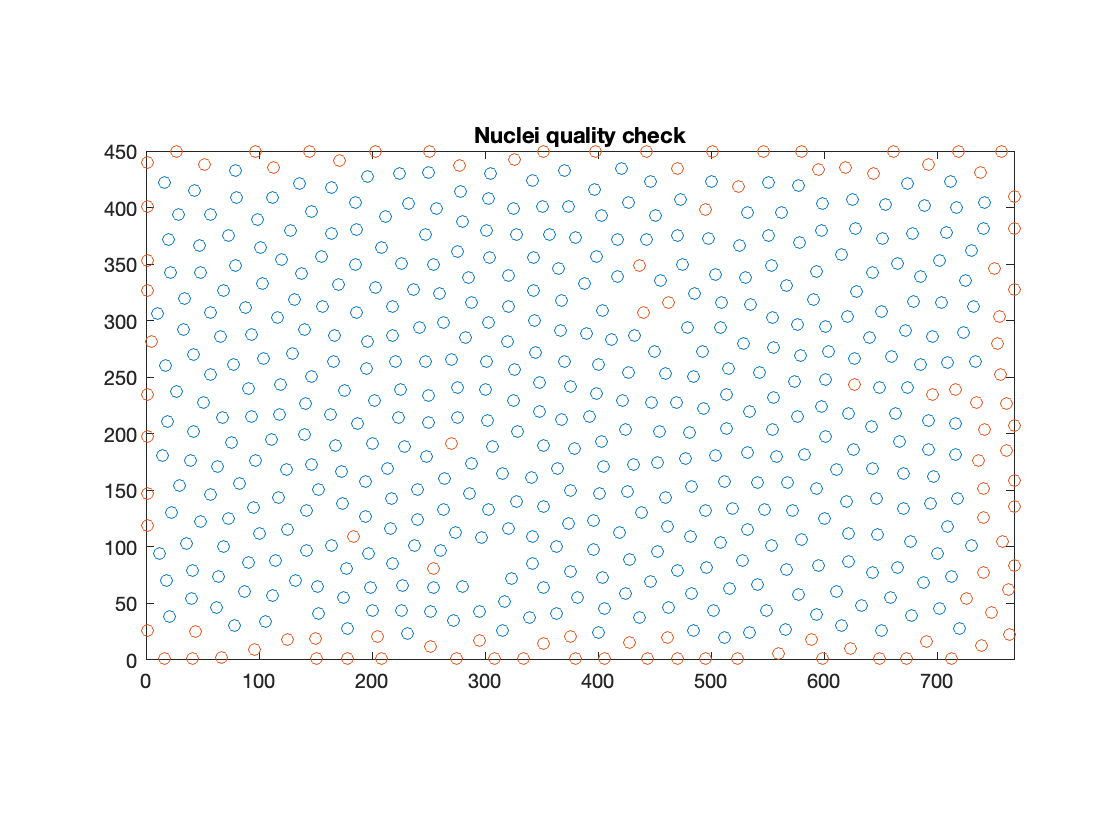

% Quality check and save the nuclei that passed the test
% Requires the nuclei to have continuous trace until lateral movement
X_pass = [];
Y_pass = [];

X_fail = [];
Y_fail = [];

schPass = [];

schnitzcells = data.sch.schnitzcells;

for i = 1:size(schnitzcells,2)
    index_s = find(schnitzcells(i).frames == initFrame);
    index_f = find(schnitzcells(i).frames == finalFrame);
    fluo_temp = max(schnitzcells(i).Fluo(index_s:index_f,:),[],2);
    result = sum(isnan(fluo_temp));
    % quality check
    if ~isempty(index_s) && ~isempty(index_f) && (index_f-index_s == finalFrame-initFrame)  ...
            && (result == 0)
        schPass = [schPass, i];
        X_pass = [X_pass, schnitzcells(i).cenx(index_s)];
        Y_pass = [Y_pass, schnitzcells(i).ceny(index_s)];
    else
        X_fail = [X_fail, schnitzcells(i).cenx(index_s)];
        Y_fail = [Y_fail, schnitzcells(i).ceny(index_s)];
    end
end

fig = figure(1);
plot(X_pass,Y_pass,'o')
hold on
plot(X_fail,Y_fail,'o')
hold off
axis equal
xlim([0 768])
ylim([0 450])
title('Nuclei quality check')

## Part 3: Compile the schnitzcells together

compile based on each frame

nucleiNum = length(schPass);

% Initialize storage
processed_data(1).xcoord = [];
processed_data(1).ycoord = [];

processed_data(1).schnitznum = [];
processed_data(1).NuclearFluo = [];
processed_data(1).SpotFluo = [];


% Compile all the nuclei in each frame and assign basic info
for i = 1:nucleiNum
    schTemp = schPass(i);
    index_s = find(schnitzcells(schTemp).frames == initFrame);
    index_f = find(schnitzcells(schTemp).frames == finalFrame);
    
    for j = index_s:index_f
        frameTemp = schnitzcells(schTemp).frames(j);
        x_coord = schnitzcells(schTemp).cenx(j);
        y_coord = schnitzcells(schTemp).ceny(j);
        fluo = max(schnitzcells(schTemp).Fluo(j,:));
        try
            processed_data(frameTemp).xcoord = [processed_data(frameTemp).xcoord, x_coord];
            processed_data(frameTemp).ycoord = [processed_data(frameTemp).ycoord, y_coord];
            processed_data(frameTemp).schnitznum = [processed_data(frameTemp).schnitznum, schTemp];
            processed_data(frameTemp).SpotFluo = [processed_data(frameTemp).SpotFluo, 0];
            processed_data(frameTemp).NuclearFluo = [processed_data(frameTemp).NuclearFluo fluo];  
        catch
            processed_data(frameTemp).xcoord = x_coord;
            processed_data(frameTemp).ycoord = y_coord;
            processed_data(frameTemp).schnitznum = schTemp;
            processed_data(frameTemp).SpotFluo = 0;
            processed_data(frameTemp).NuclearFluo = fluo;
        end
    end
end

CompiledParticles = data.particle.CompiledParticles;

% Assign particle info to all the nuclei
for i = 1:size(CompiledParticles{1,1},2)
    schnitz_num = CompiledParticles{1,1}(i).schnitz;
    for j = 1:size(CompiledParticles{1,1}(i).Frame,2)
        frame = CompiledParticles{1,1}(i).Frame(j);
        if frame<=finalFrame
            num = find(processed_data(frame).schnitznum==schnitz_num);
            processed_data(frame).SpotFluo(num) = CompiledParticles{1,1}(i).Fluo(j);
        end
    end
end

#### Compile based on each nuclei

for i = 1:nucleiNum
    for j = initFrame:finalFrame
        
        % Transform the actual frame count to analyzed frame count
        frameTemp = j-initFrame+1;
        
        CompiledNucleiData(i).xcoord(frameTemp) = processed_data(j).xcoord(i);
        CompiledNucleiData(i).ycoord(frameTemp) = processed_data(j).ycoord(i);
        
        CompiledNucleiData(i).schnitzNum(frameTemp) = processed_data(j).schnitznum(i);
        CompiledNucleiData(i).nuclearFluo(frameTemp) = processed_data(j).NuclearFluo(i)-eYFP_background;
        CompiledNucleiData(i).spotFluo(frameTemp) = processed_data(j).SpotFluo(i);
        
        
    end
end

#### Calculate average coordinate & moving average for each nuclei

for i = 1:nucleiNum
    CompiledNucleiData(i).xcoordMean = mean(CompiledNucleiData(i).xcoord);
    CompiledNucleiData(i).ycoordMean = mean(CompiledNucleiData(i).ycoord);
    CompiledNucleiData(i).nuclearFluo = movmean(CompiledNucleiData(i).nuclearFluo,3);
    CompiledNucleiData(i).spotFluo = movmean(CompiledNucleiData(i).spotFluo,3);
end

## Plot particle traces at nc14

i = 86

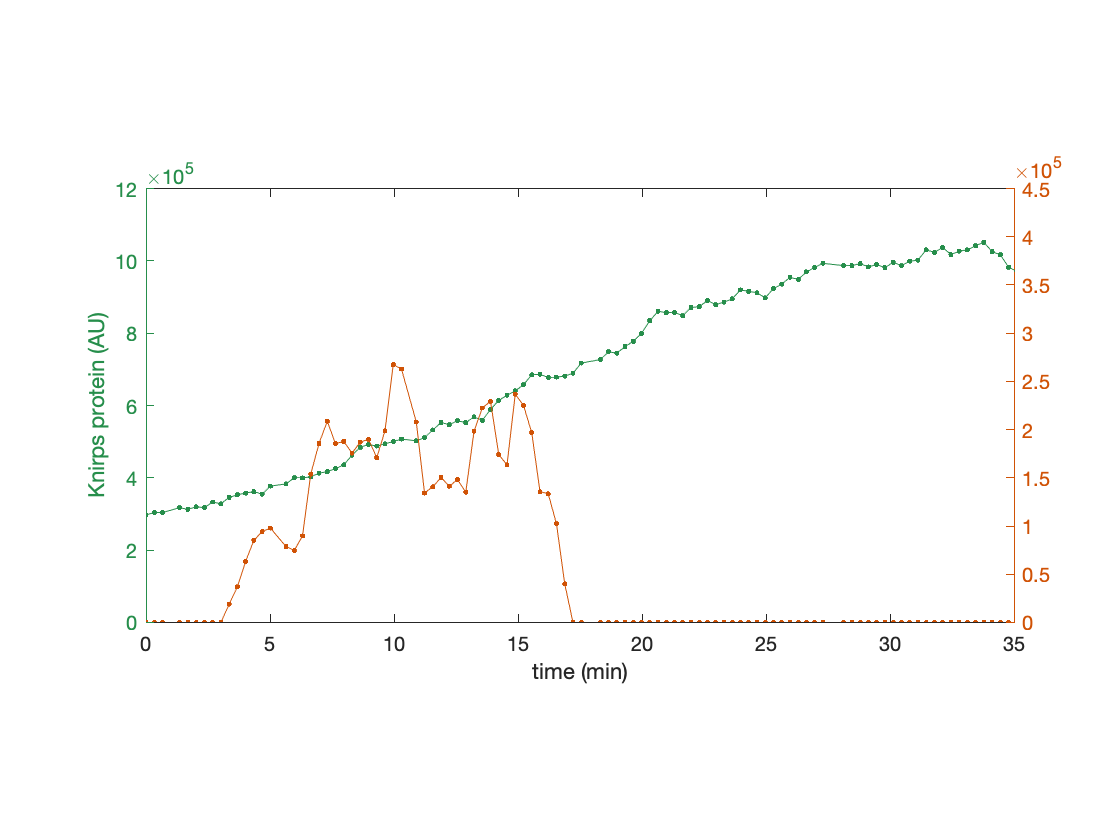

i = 349

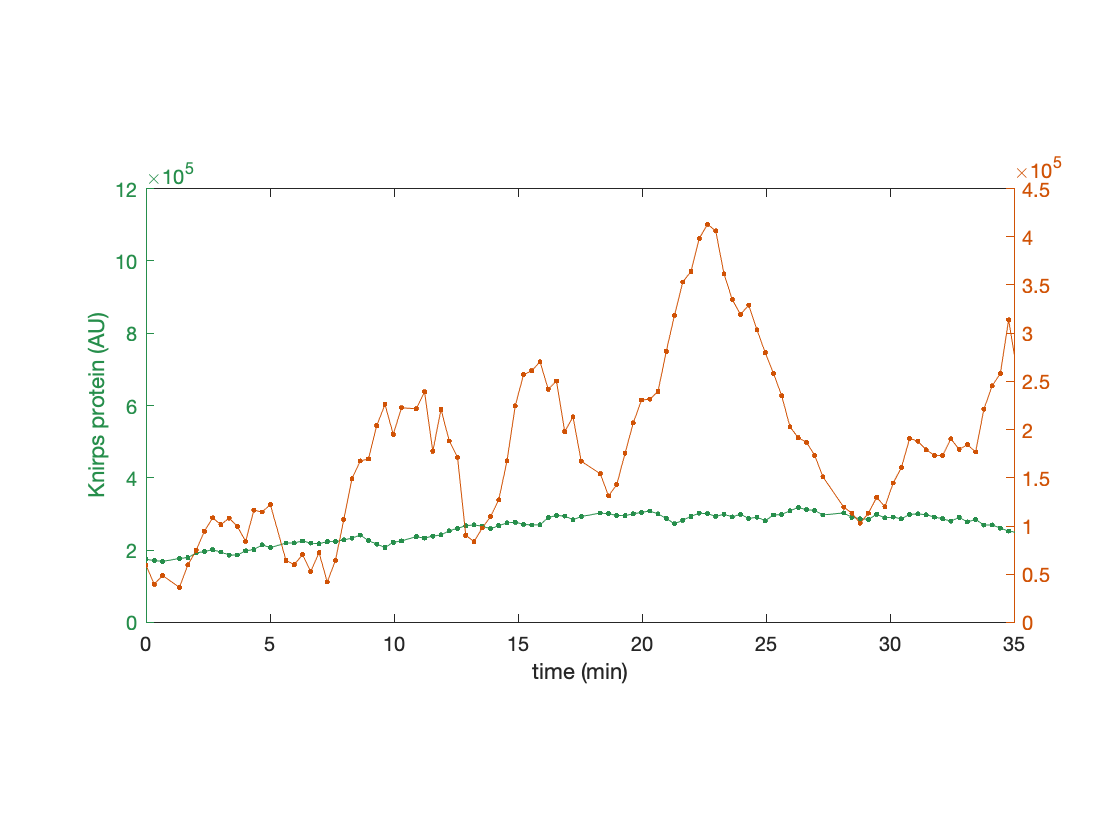

xcoord_temp = [CompiledNucleiData(:).xcoordMean];
ycoord_temp = [CompiledNucleiData(:).ycoordMean];

flag = (xcoord_temp>=387) & (xcoord_temp<=598) & (ycoord_temp>181) & (ycoord_temp<450);

%for i = find(flag==1)
for i = [86 349]
    i
    TraceFig = figure;
    set(TraceFig,'defaultAxesColorOrder',[left_color; right_color]);
    
    yyaxis left
    plot(ElapsedTime(initFrame:finalFrame),CompiledNucleiData(i).nuclearFluo,'- .')
    ylabel('Knirps protein (AU)')
    ylim([0 12E5])
    yyaxis right
    ylabel('Transcriptional Activity (AU)')
    plot(ElapsedTime(initFrame:finalFrame),CompiledNucleiData(i).spotFluo,'- .')
    ylim([0 4.5E5])
    
    xlim([0 35])
    pbaspect([2 1 1])
    xlabel('time (min)')
end